%% initialize environments
clc;
clear variables;

%% set AudioFileManipulator class parameters
input_file_path = "vaiueo2d.wav";

%% generate AudioFileManipulator instance and confirm properties
audio_file_manipulator = AudioFileManipulator(input_file_path);
audio_file_manipulator.load_properties();
audio_file_manipulator.display_properties();

--------------------------------------------
---------- Audio File Manipulator ----------
input_file_path : vaiueo2d.wav
output_file_path : default.wav
signal shape : (17500, 1)
sample_rate: 22050 [Hz]
             Filename: 'D:\名城大学\研究室\演習\MatlabPractice\SourceCode\Analysis\STRAIGHT\STRAIGHTV40_007b\vaiueo2d.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 22050
         TotalSamples: 17500
             Duration: 0.7937
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16

--------------------------------------------



%% set Cepstrum Vocoder class parameters
frame_length = 32;  % [ms]
hop_length = frame_length / 4;  % [ms]
window_mode = "hamming";
liftering_order = 2;
voicing_threshold = 0.1;

%% generate CepstrumVocoder instance and confirm properties
cepstrum_vocoder = CepstrumVocoder( ...
    audio_file_manipulator.signal, ...
    audio_file_manipulator.information.SampleRate, ...
    frame_length, ...
    hop_length, ...
    window_mode, ...
    liftering_order, ...
    voicing_threshold ...
);
cepstrum_vocoder.display_properties();

------------------------------------------------
---------------- CepstrumVocoder ---------------
signal size : (17500, 1)
sample_rate : 22050 [Hz]
window_mode : hamming
liftering_order : 2.000000 [ms]
frame_length : 706 [point]
hop_length : 176 [point]
basic_frequencies size : (99, 1)
fft_point : 2048
voicing_threshold : 0.100000
repeat_number : 10
basic_period_gain : 1.000000
synthesized_signal size : (19296, 1)
------------------------------------------------



%% set LPCPitchExtractor parameters
order = 30;
voicing_threshold = 0.304;

%% generate LinearPredictiveCodingPitchExtractor instance and confirm properties
linear_predictive_coding_pitch_extractor = LinearPredictiveCodingPitchExtractor(audio_file_manipulator.signal, audio_file_manipulator.information.SampleRate, window_mode, order, voicing_threshold);
linear_predictive_coding_pitch_extractor.display_properties();

----------------------------------------------
-- Linear Predictive Coding Pitch Extractor --
signal size : (17500, 1)
window_mode : hamming
sample_rate : 22050 [Hz]
order : 30
voicing_threshold : 0.304000
frame_length : 706 [sample]
hop_length : 176 [sample]
basic_frequencies size : (99, 1)
basic_periods size : (99, 1)
impulse_response size : (705, 1)
----------------------------------------------



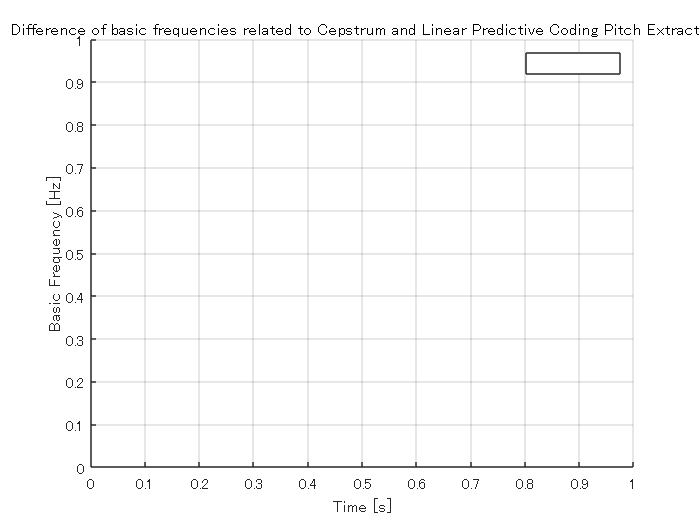

hold on;
grid on;
title("Difference of basic frequencies related to Cepstrum and Linear Predictive Coding Pitch Extractor");
xlabel("Time [s]");
ylabel("Basic Frequency [Hz]");
legend;

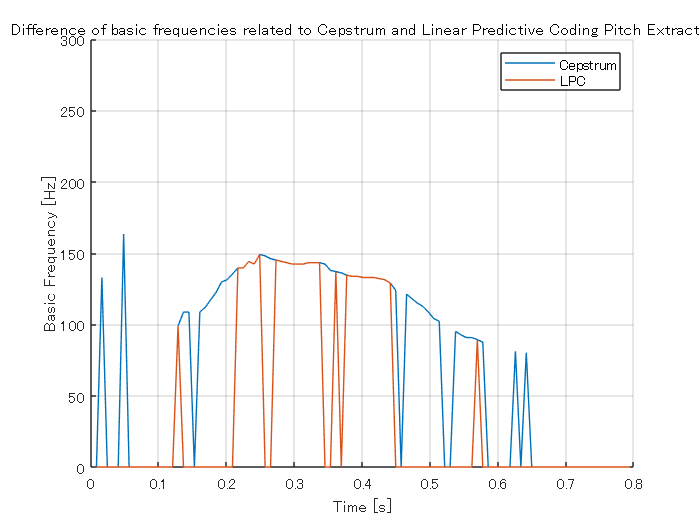

plot((1 : length(cepstrum_vocoder.basic_frequencies)) / length(cepstrum_vocoder.basic_frequencies) * length(audio_file_manipulator.signal) / audio_file_manipulator.information.SampleRate, cepstrum_vocoder.basic_frequencies, "DisplayName", "Cepstrum");
plot((1 : length(linear_predictive_coding_pitch_extractor.basic_frequencies)) / length(linear_predictive_coding_pitch_extractor.basic_frequencies) * length(audio_file_manipulator.signal) / audio_file_manipulator.information.SampleRate, linear_predictive_coding_pitch_extractor.basic_frequencies, "DisplayName", "LPC");
ylim([0 300]);

saveas(gcf, "D:/名城大学/研究室/演習/data/LPC/Difference_of_basic_frequencies_related_to_Cepstrum_and_Linear_Predictive_Coding_Pitch_Extractor.png");